# Wavetable Implementation Techniques

### Import Waveform

a_Generate = true;    % Unchecked->(loads from wavebank) Checked->(generates waveforms)
a_WaveSel = 'sawtooth';
N = 256;  % Wave size (number of samples)
wave = zeros(N,1);

Loading a wavebank (00: SINE, 07: TRIANGLE, 56: SAWTOOTH, 63: SQUARE)

if (~a_Generate)
    [waves, ~] = audioread("BASIC_WA.WAV");
    switch a_WaveSel
        case 'sine'
            wave = waves(1:N);
        case 'triangle'
            wave = waves(1+N*7:N*8);
        case 'sawtooth'
            wave = waves(1+N*56:N*57);
        case 'square'
            wave = waves(1+N*63:N*64);
    end
    clear waves;
end

Generate waves

if (a_Generate)
    step = 2 * pi / N;
    phase = 0;
    for n = 1:N
        switch a_WaveSel
            case 'sine'
                wave(n) = sin(phase);
            case 'triangle'
                wave(n) = sawtooth(phase + pi/2,0.5);
            case 'sawtooth'
                wave(n) = sawtooth(phase + pi);
            case 'square'
                wave(n) = square(phase);                
        end
        phase = phase + step;
    end
end
clear step phase n;

## Waveform Preprocessing (anti-aliasing)

fs = 48000;   % sampling frequency (Hz)
f = 406.45;    % playback fundamental frequency (Hz)

Band limiting the waveform with fourier transform

banWave = fftbandlimit(fs, f, wave, N);

Compare original waveform and bandlimited waveform

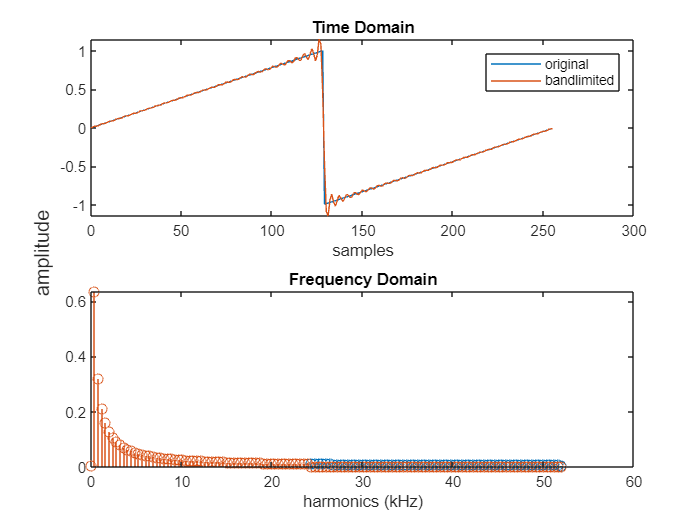

% compute original waveform harmonics
fW = fft(wave);
ampW = abs(fW/N);
ampW = ampW(1:N/2+1);
ampW(2:end-1) = 2*ampW(2:end-1);
% compute bandlimited waveform harmonics
fbW = fft(banWave);
ampbW = abs(fbW/N);
ampbW = ampbW(1:N/2+1);
ampbW(2:end-1) = 2*ampbW(2:end-1);
n = 0:N-1;
h = (0:N/2)*f/1000;

figure
til = tiledlayout(2,1);

% Plot waveforms
ax1 = nexttile;
plot(ax1, n,wave, 'DisplayName','original');
hold on
plot(ax1, n,banWave, 'DisplayName','bandlimited');
hold off
title(ax1,'Time Domain')
xlabel(ax1,'samples')
legend

% Plot harmonics
ax2 = nexttile;
stem(ax2, h,ampW);
hold on
stem(ax2, h,ampbW);
hold off
title(ax2,'Frequency Domain')
xlabel(ax2,'harmonics (kHz)')

ylabel(til, 'amplitude')
til.TileSpacing = 'compact';

clear fW fbW ampW ampbW n h til ax1 ax2

## Sample & Interpolate

dur = 1;        % output duration (s)
a_interp = "hermite";   % Interpolation method
a_useBandlimit = true;              % Unchecked->(uses original waveform) Checked->(uses bandlimited waveform)

p = N*f/fs;                        % phase increment
NOut = ceil(dur * fs);             % number of output samples
out = zeros(NOut,1);               % output

Simulate wavetable oscilattor

phase = 0;      % running phase
for n = 1:NOut
    if phase >= N
        phase = phase - N;
    end
    % Interpolate
    switch a_interp
        case 'linear'
            if (a_useBandlimit)
                out(n) = linInterp(phase, banWave, N);
            else
                out(n) = linInterp(phase, wave, N);
            end
        case 'cubic'
            if (a_useBandlimit)
                out(n) = cubInterp(phase, banWave, N);
            else
                out(n) = cubInterp(phase, wave, N);
            end
        case 'hermite'
            if (a_useBandlimit)
                out(n) = hermInterp(phase, banWave, N);
            else
                out(n) = hermInterp(phase, wave, N);
            end
    end
    phase = phase + p;
end
clear phase n

Display output wave

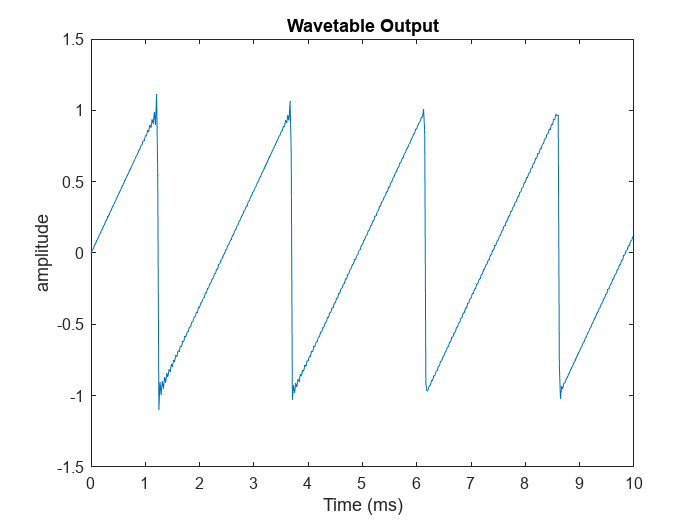

t = (0:NOut-1)/fs;

figure
% Create plot of out
plot(1000*t,out);

xlim([0,10]);
% Add ylabel, title, and legend
xlabel("Time (ms)")
ylabel("amplitude")
title("Wavetable Output")

clear t
soundsc(out,fs)

## FFT Analyse Output

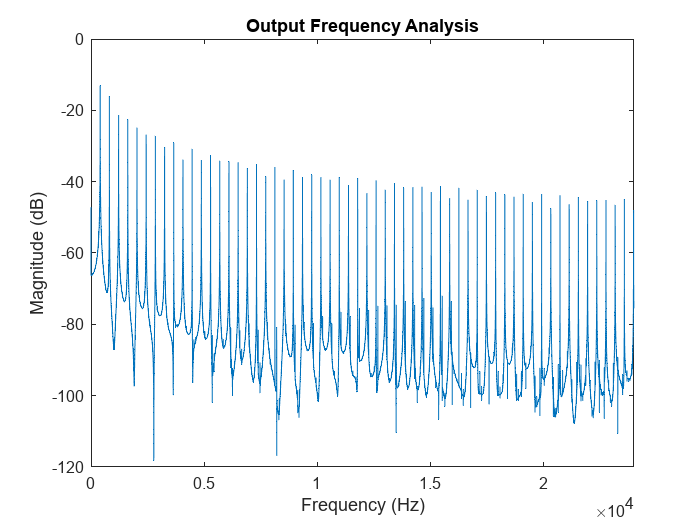

w = window(@hamming,length(NOut));
y = fft(w.*out);
mag = db(y/NOut);
mag = mag(1:NOut/2+1);
amp = abs(y/NOut);
amp = amp(1:NOut/2+1);
amp(2:end-1) = 2*amp(2:end-1);
freq = fs*(0:NOut/2)/NOut;

figure
plot(freq, mag)

xlim([0,fs/2]);
title('Output Frequency Analysis')
ylabel('Magnitude (dB)')
xlabel('Frequency (Hz)')